# Theta Plotter

Daniel Dymond 2021

Plots the position of the ABB-2600-12/1.85 Robot for a given configuration defined by theta angles at each joint.

## User Parameters

% Theta Position for Frames 1-7

%T_60 = [ 0   1   0   1125
%          1   0   0   325
%          0   0   -1  473 
%          0   0   0   1    ];

%[theta] = ABB_IK_solveTheta(T_60)

% Zero Position
theta = [0 0 0 0 0 0];

% Position O
%theta = [0.0598    0.0437   -0.6301    0.1078   -0.5891    3.0519];
% 0.0598    0.0437   -0.6301   -3.0338    0.5891   -0.0897
% 0.0598    0.0437   -0.6301    0.1078   -0.5891    3.0519
% -3.0818    0.2766    3.1186    0.2343    0.2604   -0.2266
% -3.0818    0.2766    3.1186    3.3759   -0.2604    2.9149

% Position A
%theta = [0.0222   -0.6604   -0.4992         0    0.4112   -1.5486 0];

## Plot Generation

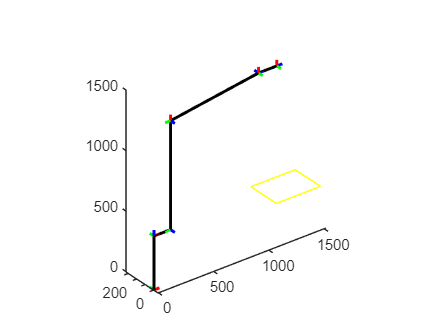

op =   1×3 Line array:

    Line    Line    Line


% Create a new Plot
outputPlot = figure(1);
view(3);
hold on;
[op, ~, ~, ~] = ABB_Plot(theta(1,:), 1, outputPlot)

theta = rad2deg(theta)

theta =      0     0     0     0     0     0
